# MatLab Analysis For Air Levitation Control System

### Defining Variables that We will Use

% Transfer function coefficients
numerator = [10.06];
denominator = [1, 2.646, 6.462, 5.49];

% Sampling time
Ts = 0.1; 

% PID controller parameters
Kp = 0.36962;
Ki = 0.50657;
Kd = 0.067425;

% SetPoint --> Input Value
SP = 15;     

% Setpoint of step response
SP_Step = 1;

# Question 1

- Convert the experimental transfer function from S Domain to Z Domain using MATLAB with two different methods

### Method 1: Using c2d function

- Answer of Part 1 of ***Question 8***

***Question 8: ***Get the result of Preceding the plant a ZOH results before and after the PID tunning.  

sys_s = tf(numerator, denominator);
sys_z_c2d = c2d(sys_s, Ts, 'zoh') % 'zoh' stands for zero-order hold

sys_z_c2d =
 
  0.001566 z^2 + 0.005853 z + 0.001372
  ------------------------------------
   z^3 - 2.709 z^2 + 2.481 z - 0.7675
 
Sample time: 0.1 seconds
Discrete-time transfer function.



### Method 2: Using bilinear function

%bilinear(numerator, denominator, 1/Ts) % or we can use c2d function with 'tustin' method
sys_z_bilinear = c2d(tf(numerator, denominator), Ts, 'tustin')

sys_z_bilinear =
 
  0.001094 z^3 + 0.003283 z^2 + 0.003283 z + 0.001094
  ---------------------------------------------------
           z^3 - 2.71 z^2 + 2.483 z - 0.7685
 
Sample time: 0.1 seconds
Discrete-time transfer function.



### Method 3: Using Euler function

G_d_modified_euler = c2d(sys_s, Ts, 'method', 'euler')

G_d_modified_euler =
 
  0.002198 z^2 + 0.004396 z + 0.002198
  ------------------------------------
   z^3 - 2.709 z^2 + 2.481 z - 0.7675
 
Sample time: 0.1 seconds
Discrete-time transfer function.



# Question 2 

- Tune the Z Domain transfer function using MATLAB PID Tuner GUI and mention the tunning results as P, I, D. 

% PID Tuner GUI
pidTuner(sys_z_c2d,'pid');

# Question 3

- Get the S and Z Domain PID transfer functions. 

### S Domain PID transfer function

Create the continuous-time PID transfer function

num_pid_s = [Kd, Kp, Ki];   % Coefficients of the derivative, proportional, and integral terms
den_pid_s = [1, 0];         % Denominator coefficients for a simple unity feedback system
sys_pid_s = tf(num_pid_s, den_pid_s)

sys_pid_s =
 
  0.06742 s^2 + 0.3696 s + 0.5066
  -------------------------------
                 s
 
Continuous-time transfer function.



### Z Domain PID transfer function

Discretize the continuous-time PID transfer function using the 'tustin' method

sys_pid_z = c2d(sys_pid_s, Ts, 'tustin') 

sys_pid_z =
 
  1.743 z^2 - 2.646 z + 1.004
  ---------------------------
            z^2 - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.



% We used tustin which handle the improper system and proper systems too 
% Why ? because our system is unstable in which the degree of the numerator is greater than the degree of the denomenator
% and the poles is equal 0 which make the system unstable  

# Question 4

- Get the total transfer function after the PID Tunning (System + Controller) in both Z and S Domain. 

### Total Transfer Function after PID in S Domain

% Calculate the total transfer function in the Laplace (s) domain
sys_total_s = sys_s * sys_pid_s

sys_total_s =
 
      0.6783 s^2 + 3.718 s + 5.096
  ------------------------------------
  s^4 + 2.646 s^3 + 6.462 s^2 + 5.49 s
 
Continuous-time transfer function.



### Total Transfer Function after PID in Z Domain

% Calculate the total transfer function in the Z domain
sys_total_z = series(sys_z_c2d, sys_pid_z)

sys_total_z =
 
  0.002731 z^4 + 0.006059 z^3 - 0.01152 z^2 + 0.002246 z + 0.001378
  -----------------------------------------------------------------
     z^5 - 2.709 z^4 + 1.481 z^3 + 1.941 z^2 - 2.481 z + 0.7675
 
Sample time: 0.1 seconds
Discrete-time transfer function.



# Question 5

- Get Steady State Error before and after the PID Control in Z Domain.

### Steady State Error Before PID in Z Domain

[y, t] = step(SP * sys_z_c2d);           % get the response of the system to a step with amplitude SP
SSerror_Before_PID = abs(SP - y(end))   % get the steady-state error

SSerror_Before_PID = 12.5042

### Steady State Error After PID in Z Domain

- Answer of Part 2 of ***Question 8***

***Question 8: ***Get the result of Preceding the plant a ZOH results before and after the PID tunning.  

% Closed-loop transfer function after PID control
sys_closed_loop = feedback(series(sys_z_c2d, sys_pid_z), 1)

sys_closed_loop =
 
  0.002731 z^4 + 0.006059 z^3 - 0.01152 z^2 + 0.002246 z + 0.001378
  -----------------------------------------------------------------
     z^5 - 2.706 z^4 + 1.487 z^3 + 1.929 z^2 - 2.479 z + 0.7689
 
Sample time: 0.1 seconds
Discrete-time transfer function.



[y, t] = step(SP * sys_closed_loop);  % get the response of the system to a step with amplitude SP
SSerror_After_PID = abs(SP - y(end))       % get the steady-state error

SSerror_After_PID = 0.0268

# Question 6

- Get Transient response parameters and graph before and after the PID Control on step input in Z Domain.

### Display transient response parameters before and after PID control

% Transient Response Parameters Before PID Control
info_before_pid = stepinfo(sys_z_c2d);
disp(info_before_pid);

         RiseTime: 1.2000
    TransientTime: 4.4000
     SettlingTime: 4.4000
      SettlingMin: 1.6933
      SettlingMax: 1.8902
        Overshoot: 3.1544
       Undershoot: 0
             Peak: 1.8902
         PeakTime: 2.4000



% Transient Response Parameters After PID Control
info_after_pid = stepinfo(SP * sys_closed_loop);
disp(info_after_pid);

         RiseTime: 1.2000
    TransientTime: 7
     SettlingTime: 7
      SettlingMin: 13.7899
      SettlingMax: 16.2562
        Overshoot: 8.3744
       Undershoot: 0
             Peak: 16.2562
         PeakTime: 2.3000



### Graph before and after the PID Control on step input in Z Domain

Plot step response before and after PID control

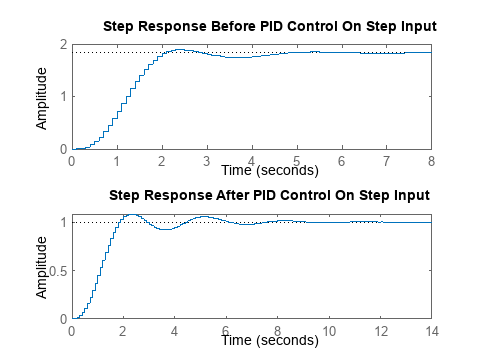

figure;
subplot(2,1,1);
step(SP_Step * sys_z_c2d);
title('Step Response Before PID Control On Step Input');

subplot(2,1,2);
step(SP_Step * sys_closed_loop);
title('Step Response After PID Control On Step Input');

# Question 7

- Plot Step response plot before and after the PID response in Z Domain. 

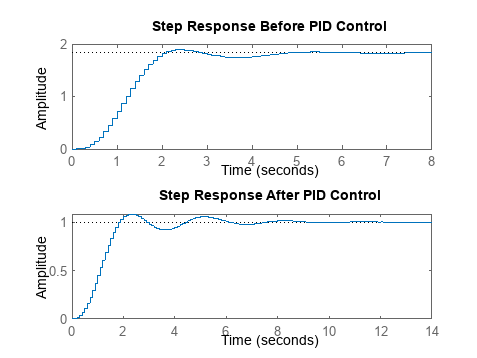

figure;
subplot(2,1,1);
step(SP * sys_z_c2d);
title('Step Response Before PID Control');

subplot(2,1,2);
step(SP * sys_closed_loop);
title('Step Response After PID Control');

# Question 9 & 10

***Question 9: ***Determine the system stability using MATLAB isStable function before and after PID in Z Domain. 

***Question 10: ***Determine The system stability before and after adding the PID Control (using Z domain plot) in Z Domain. 

### Determine the system stability before the PID tunning

% Check stability before PID control
isStable_before = isstable(sys_z_c2d)

isStable_before = logical
   1


## Determine the system stability after the PID tunning

% Check stability after PID control
isStable_after = isstable(sys_closed_loop)

isStable_after = logical
   1


## Why we didn't use zoh ?

Checking if the S Domain is stable to use ZOH

isStable_sys_pid_s = isstable(sys_pid_s)

isStable_sys_pid_s = logical
   0


## Reason for using tustin

% Check causality
isCausal = isproper(sys_pid_s, 'Causal', true)

isCausal = logical
   0


% Check properness
isProper = isproper(sys_pid_s, 'Strict', true)

isProper = logical
   0


% Only proceed with discretization if the system is causal, proper, and stable
if isCausal && isProper 
    disp('System is suitable for discretization.');
else
    disp('System is not suitable for discretization.');
end

System is not suitable for discretization.


## Plot poles in the Z domain before PID control

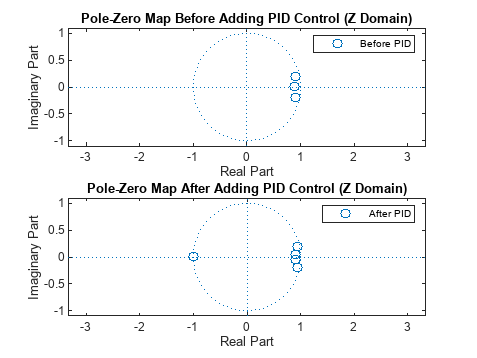

figure;
subplot(2,1,1);
zplane(pole(sys_z_c2d));
title('Pole-Zero Map Before Adding PID Control (Z Domain)');
legend('Before PID');

% Plot poles in the Z domain after PID control
subplot(2,1,2);
zplane(pole(sys_closed_loop));
title('Pole-Zero Map After Adding PID Control (Z Domain)');
legend('After PID');

# Question 11

- Plot the Root Locus for the system before and after PID in Z Domain. 

## Plot Root Locus Before and After adding PID in Z domain

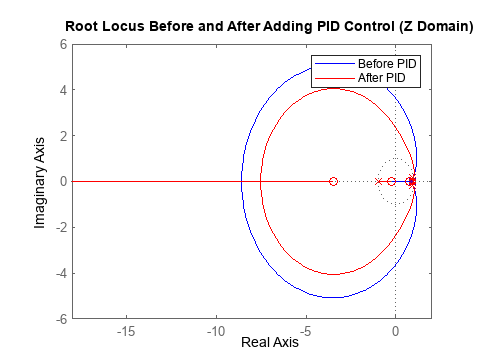

figure;
rlocus(sys_z_c2d, '-b', sys_closed_loop, '-r');
title('Root Locus Before and After Adding PID Control (Z Domain)');
legend('Before PID', 'After PID');